clear;

## Q4

% globals
A0 = [-6.25; 0.00];
X0 = [ 0.40; 0.00];
V0 = [ 0.00; 0.50];
h = 10^-4;
N = ceil(2*pi/h)*30;
T = N/30;
cuts = [1 2 3 4 5 10 15 20 25 30];

A = @(x1,x2) [-x1 ./ sqrt(x1^2+x2^2).^3; -x2 ./ sqrt(x1^2+x2^2).^3];
L = @(x1,x2,v1,v2) x1.*v2 - x2.*v1;
H = @(x1,x2,v1,v2) 1/2*(v1.^2 + v2.^2) - 1./sqrt(x1.^2 + x2.^2);

tbl = zeros(10, 4);
traj = cell(1, 3);
mom = cell(1, 3);
energy = cell(1, 3);

**Leap-Frog**

X = zeros(2,N);
X(:,1) = X0;
V = zeros(2,N);
V(:,1) = V0;

for i = 1:N-1
    Vhalf(:,1) = V(:,i) + A(X(1,i), X(2,i))*h/2;
    X(:,i+1) = X(:, i) + Vhalf(:,1)*h;
    V(:,i+1) = Vhalf(:,1) + A(X(1,i+1), X(2,i+1))*h/2;
end

for i = 1:10
    tbl(i,1) = V(1,cuts(i)*T);
end

traj{1} = X(2,:);
mom{1} = L(X(1,:), X(2,:), V(1,:), V(2,:));
energy{1} = H(X(1,:), X(2,:), V(1,:), V(2,:));

**Strormer-Verlet**

% integration
X = zeros(2,N);
X(:,1) = X0;
X(:,2) = X0 + V0*h + 1/2*A0*h^2;

for i = 2:N-1
    X(:,i+1) = 2*X(:,i) - X(:,i-1) + A(X(1,i), X(2,i))*h^2;
end

% differentiation
% c = [0 -1 zeros(1,N-2)];
% r = [0  1 zeros(1,N-2)];
% FD = 1/(2*h)*toeplitz(c,r);
% FD(1,1) = -1/h; FD(1,2) = 1/h;
% FD(end,end-1) = -1/h; FD(end,end) = 1/h; 

D = sparse(1:N,1:N,-2*ones(1,N),N,N);
E = sparse(2:N,1:N-1,ones(1,N-1),N,N);
SD = 1/h^2*(E+D+E');

V = zeros(2,N);
V(1,:) = SD*X(1,:)';
V(2,:) = SD*X(2,:)';

for i = 1:10
    tbl(i,2) = V(1,cuts(i)*T);
end

traj{2} = X(2,:);
mom{2} = L(X(1,:), X(2,:), V(1,:), V(2,:));
energy{2} = H(X(1,:), X(2,:), V(1,:), V(2,:));

**Heun's Method**

X = zeros(2,N);
X(:,1) = X0;
V = zeros(2,N);
V(:,1) = V0;

for i = 1:N-1
    K1X = h * V(:,i);
    K1V = h * A(X(1,i), X(2,i));
    
    K2X = h * V(:,i) + h*K1V;
    K2V = h * A(X(1,i) + h*K1X(1,1), ...
                X(2,i) + h*K1X(2,1));

    X(:,i+1) = X(:,i) + 1/2*(K1X + K2X);
    V(:,i+1) = V(:,i) + 1/2*(K1V + K2V);
end

for i = 1:10
    tbl(i,3) = V(1,cuts(i)*T);
end

traj{3} = X(2,:);
mom{3} = L(X(1,:), X(2,:), V(1,:), V(2,:));
energy{3} = H(X(1,:), X(2,:), V(1,:), V(2,:));

**BDF2**

X = zeros(2,N);
X(:,1) = X0;
V = zeros(2,N);
V(:,1) = V0;

X(:,2) = X(:,1) + h*V(:,1);
V(:,2) = V(:,1) + h*A(X(1,1), X(2,1));

for i = 2:N-1
    F = @(x) [x(1) - 4/3*X(1,i) + 1/3*X(1,i-1) - 2*h*x(3);
              x(2) - 4/3*X(2,i) + 1/3*X(2,i-1) - 2*h*x(4);
              x(3) - 4/3*V(1,i) + 1/3*V(1,i-1) - 2*h*(-x(1) / sqrt(x(1)^2+x(2)^2)^3);
              x(4) - 4/3*V(2,i) + 1/3*V(2,i-1) - 2*h*(-x(2) / sqrt(x(1)^2+x(2)^2)^3)];
    options = optimset('Display','off');
    sol = fsolve(F, [X(1,i) X(2,i) V(1,i) V(2,i)], options);
    X(1,i+1) = sol(1);
    X(2,i+1) = sol(2);
    V(1,i+1) = sol(3);
    V(2,i+1) = sol(4);
end

**ode45**

Y0 = [0.4; 0; 0; 0.5];
options = odeset('RelTol', 1e-8, 'AbsTol', 1e-8);
soln45 = ode45(@(t,y) keplerODE(t,y), [0 60*pi], Y0, options);

for i = 1:10
    if isequal(i,10)
        s = deval(soln45, max(soln45.x));
    else
        s = deval(soln45, cuts(i)*6.2832);
    end
    tbl(i,4) = s(3);
end

**Trajectories**

T = tiledlayout(1,1);
T.Units = 'inches';
T.OuterPosition = [0 0 6 3];

% preamble
f1q4 = nexttile();
legend('location', 'southwest');
xlabel("Time");
axis([0 2*pi -0.7 0.2]);

name = ["Leap-Frog", "Strormer-Verlet", "Heun's Method", "ode45"];
tt = 0:h:2*pi; len = length(tt);

hold on;
for i = 1:4
    if i==4
        yy = deval(soln45,tt,2);
    else
        yy = traj{i};
    end
    plot(tt, yy(1:len), ...
        'DisplayName', name(i));
end
hold off;
exportgraphics(f1q4, [pwd '/Figures/HW2_q4_traj_start.png']);

T = tiledlayout(1,1);
T.Units = 'inches';
T.OuterPosition = [0 0 6 3];

% preamble
f2q4 = nexttile();
legend('location', 'southwest');
xlabel("Time");

name = ["Leap-Frog", "Strormer-Verlet", "ode45"];
tt = N/30*29*h : h : 60*pi; 
len = length(tt);

hold on;
for i = 1:3
    if i==3
        yy = deval(soln45,tt,2);
        plot(tt, yy, 'DisplayName', name(i));
    else
        yy = traj{i};
        plot(tt, yy(N/30*29 : N/30*29+len-1), ...
            'DisplayName', name(i));
    end
end
hold off;
exportgraphics(f2q4, [pwd '/Figures/HW2_q4_traj_end.png']);

% drift
maxInit = max(soln45.y(2,1:1645));
minInit = min(soln45.y(2,1:1645));
maxEnd = max(soln45.y(2,1645*29:end));
minEnd = min(soln45.y(2,1645*29:end));

driftMax = norm(maxInit - maxEnd)
driftMin = norm(minInit - minEnd)

**Angular Momentum**

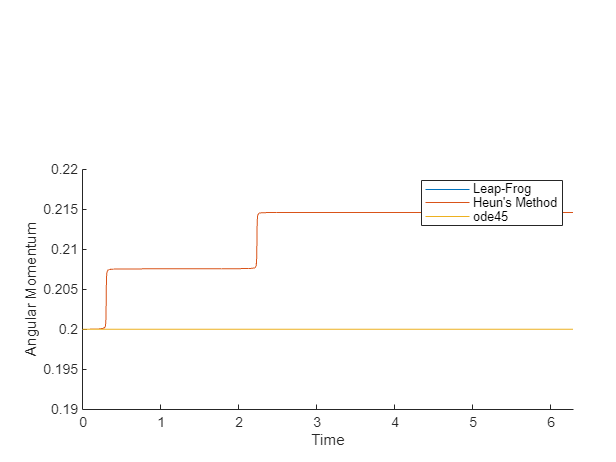

T = tiledlayout(1,1);
T.Units = 'inches';
T.OuterPosition = [0 0 6 3];

% preamble
f3q4 = nexttile();
legend('location', 'northeast');
xlabel("Time"); ylabel("Angular Momentum");
xlim([0 2*pi]); ylim([0.19 0.22]);

name = ["Leap-Frog", "Strormer-Verlet", "Heun's Method", "ode45"];
tt = 0:h:2*pi*30; len = length(tt);

hold on;
for i = 1:4
    if i==4
        M = soln45.y;
        yy = L(M(1,:), M(2,:), M(3,:), M(4,:));
        plot(soln45.x, yy, 'DisplayName', name(i));
    elseif i==2
    else
        yy = mom{i};
        plot(tt, yy(1:len), ...
            'DisplayName', name(i));
    end
end
hold off;
exportgraphics(f3q4, [pwd '/Figures/HW2_q4_ang_mom.png']);

**Energy**

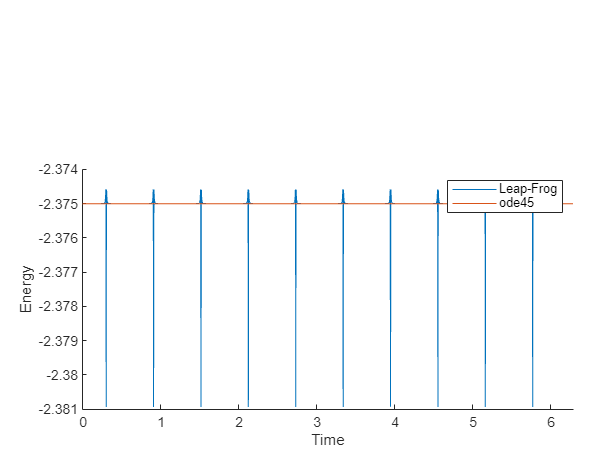

T = tiledlayout(1,1);
T.Units = 'inches';
T.OuterPosition = [0 0 6 3];

% preamble
f4q4 = nexttile();
legend('location', 'northeast');
xlabel("Time"); ylabel("Energy");
xlim([0 2*pi]);

name = ["Leap-Frog", "Strormer-Verlet", "Heun's Method", "ode45"];
tt = 0:h:2*pi*30; len = length(tt);

hold on;
for i = 1:4
    if i==4
        M = soln45.y;
        yy = H(M(1,:), M(2,:), M(3,:), M(4,:));
        plot(soln45.x, yy, 'DisplayName', name(i));
    elseif i==2
    elseif i==3
    else
        yy = energy{i};
        plot(tt, yy(1:len), ...
            'DisplayName', name(i));
    end
end
hold off;
% exportgraphics(f4q4, [pwd '/Figures/HW2_q4_energy.png']);
exportgraphics(f4q4, [pwd '/Figures/HW2_q4_energy_osc.png']);